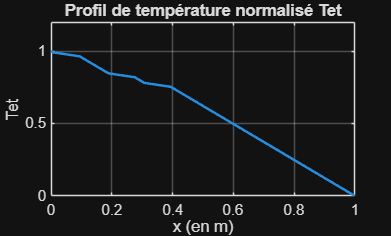

%-------------------------- Code Percolation en conduction thermique 1D--------------------------------------

%----------------------- -------------Cas hétérogène ------------------------------------------------------

clear all;
close all;

Lx = 1; %Longueur x
r = 5; % Rayon des charges
fs = 0.2; % Fraction surfacique de charges
kc = 4; % Conductivité charges
ki = 1; % Conductivité isolant
Nx = 128; % Nb de points x

[kl, f]= PercolationGenerator1D(Nx, r, fs, false); %Conductivité thermique
[Tet, k, dx] = resolutionThermique1D(Nx, kl, kc, ki, Lx);


x = 0:dx:Lx;
figure;
plot(x, Tet, 'LineWidth', 1.5)
title('Profil de température normalisé Tet')
xlabel('x (en m)'); ylabel('Tet')
grid on

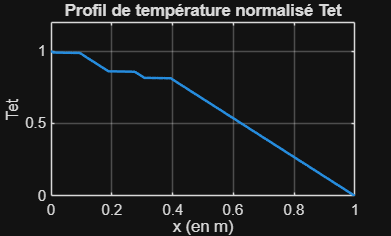


[Tet, k, dx] = resolutionThermique1D(Nx, kl, kc*10, ki, Lx);

x = 0:dx:Lx;
figure;
plot(x, Tet, 'LineWidth', 1.5)
title('Profil de température normalisé Tet')
xlabel('x (en m)'); ylabel('Tet')
grid on

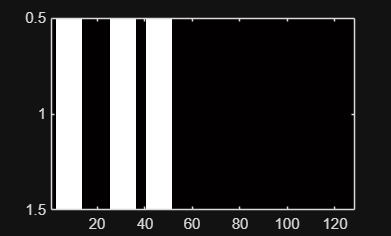


figure;
imagesc(kl);
colormap(hot);